# Animate EPANET simulation results

**Clear - Start toolkit**

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


**Load network**

inpname = 'net2-cl2.inp';
msxname = 'net2-cl2.msx';
d = epanet(inpname);

EPANET version {20200} loaded (EMT version {v2.2.1}).
Loading File "net2-cl2.inp"...
Input File "net2-cl2.inp" loaded successfully.


d.loadMSXFile(msxname);

**Set simulation settings**

t_d = 1;
duration_hrs = t_d*5;
duration_sec = duration_hrs*60*60;
d.setTimeSimulationDuration(duration_sec);

**Run computed quality analysis of CL2**

% species = d.getMSXSpeciesNameID;
species = 'CL2'; 

Qmsx_species_CL2 = d.getMSXComputedQualitySpecie(species);
bulk_specie_id = species;
wall_specie_id = ''; 

**Set movie related settings**

colorbarposition = 'southoutside';
hyd = 0; % code 1 for hydraulics, code 0 for quality
labelvalues = [0 0.2 0.4 0.6 0.8];
labelstrings ={'0' '0.2' '0.4' '0.6' '0.8'};
ylabelinfo = {'Chlorine (mg/L)', 12};
titleinfo = {'Chlorine after',12};
V = Qmsx_species_CL2.NodeQuality';
L = Qmsx_species_CL2.LinkQuality';
fig = [];                   % Use a new figure window
movname = [inpname(1:end-4),'.avi']; % Movie name
quality = 100;              % 0-100 movie quality (related to data compression)
fps = 8;                    % Frame rate - # to display per second
PData.c = 'jet';            % colormap - see 'help colormap'
PData.logtransv = 'n';      % Do not log transform the data
PData.vmin = 0;             % min vertex value for plot color mapping
PData.vmax = max(max(V));   % max vertex value
PData.lmin = 0;
PData.lmax = max(max(L));
PData.lwidth = 2;           % Width of links in points
PData.vsize = 5;            % Size of vertices in points (0 == omits verts)
PData.tsize = 10;           % Size of tank/reservoir nodes
PData.legend = 'v';         % Show a colorbar legend for vertex data
SData = [];                 % No special node symbols

**Write the Movie File**

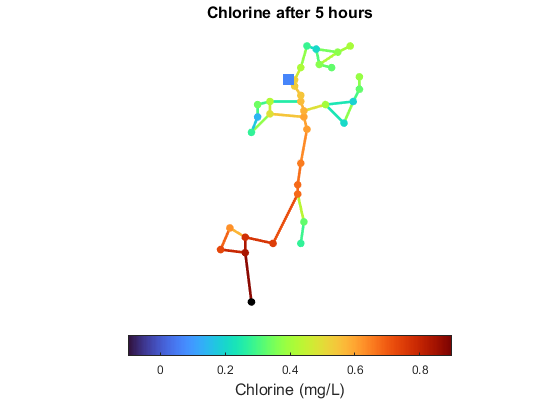

movie_network(V,L,fig,movname,...
    quality,fps,PData,SData,d,bulk_specie_id,[],...
hyd,labelvalues,labelstrings,ylabelinfo,titleinfo,colorbarposition);


% Show the Movie
winopen(movname);